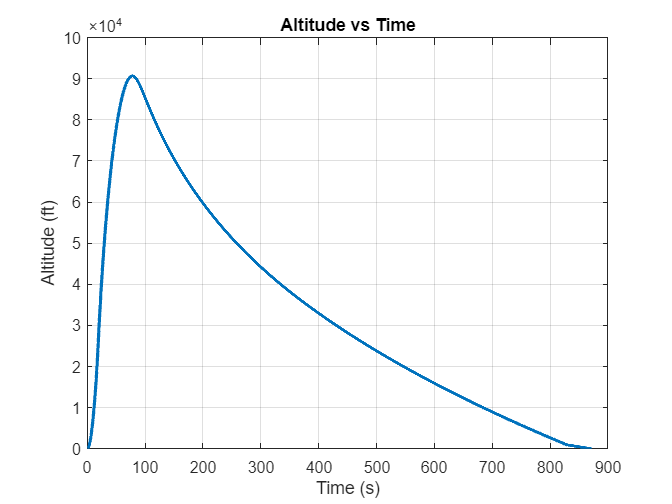

if ~exist('S', 'var')
    denebsim
end

if ~exist('Deneb', 'var')
    ROCKET
end

T_ascent = [T_Powered; T_Ballistic+T_Powered(end)];
S_ascent = [S_Powered; [S_Ballistic, S_Powered(end,3)*ones(size(S_Ballistic(:,1)))]];
T_descent = [T_Drogue; T_Main+T_Drogue(end)];
S_descent = [[S_Drogue, S_Powered(end,3)*ones(size(S_Drogue(:,1)))]; [S_Main, S_Powered(end,3)*ones(size(S_Main(:,1)))]];

T = [T_Powered; T_Ballistic+T_Powered(end); T_Drogue+T_Powered(end)+T_Ballistic(end);T_Main+T_Drogue(end)+T_Powered(end)+T_Ballistic(end)];
S = [S_Powered(:,1:2); S_Ballistic; S_Drogue; S_Main];

altitude = S(:,1)*3.28084;
velocity = S(:,2)*3.28084;
mach = calcMach(S_ascent);

[cd, dragforce, skindrag, maxqstuff] = dragAnalysis(T_Powered, S_Powered, Deneb.DIAMETER^2*pi/4, Deneb);

[totalthrust, massthrust, pressurethrust] = thrustAnalysis(T_Powered, S_Powered, Deneb);

ttw = totalthrust./(S_Powered(:,3)'*9.81);
figure
altvstime = PrettyPlot(T, altitude, "Time (s)", "Altitude (ft)", "Altitude vs Time");

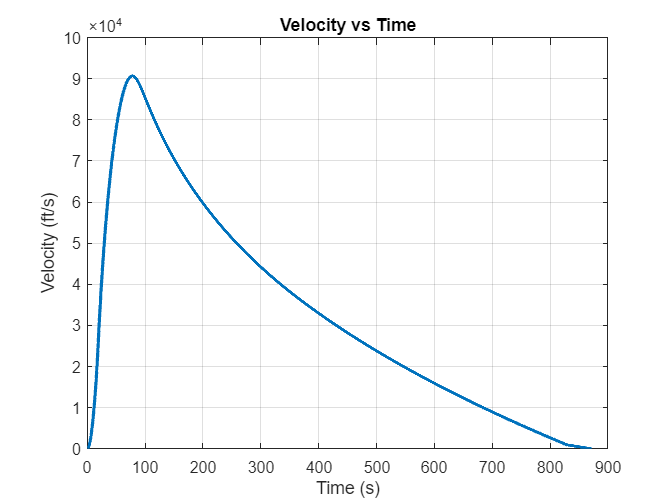

velvstime = PrettyPlot(T, altitude, "Time (s)", "Velocity (ft/s)", "Velocity vs Time");

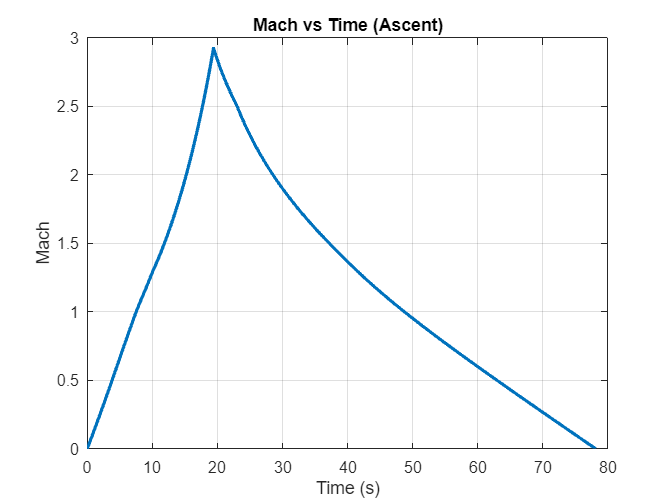

machvstime = PrettyPlot(T_ascent, mach, "Time (s)", "Mach", "Mach vs Time (Ascent)");

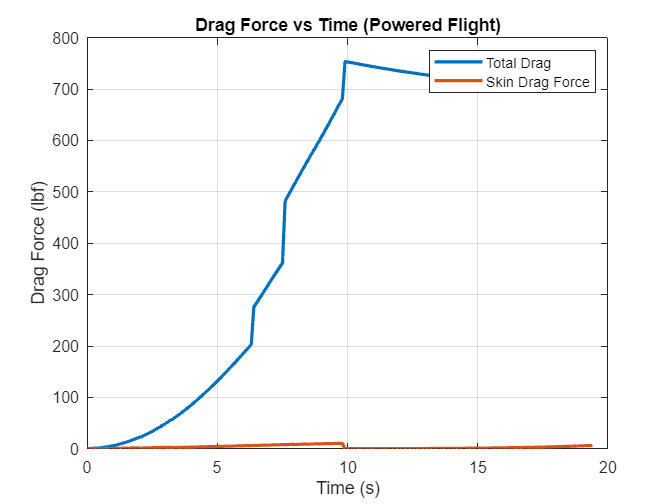

bothdragsvstime = PrettyPlot(T_Powered, [dragforce; skindrag] * 0.224809, "Time (s)", "Drag Force (lbf)", "Drag Force vs Time (Powered Flight)");
legend(bothdragsvstime, "Total Drag", "Skin Drag Force");

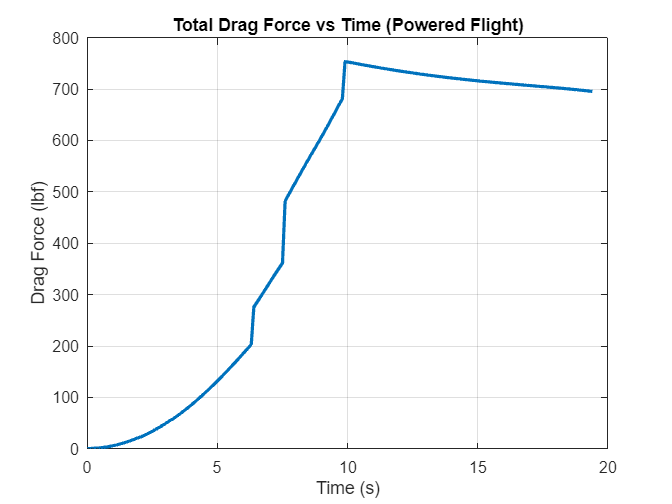

figure
totaldragvstime = PrettyPlot(T_Powered, dragforce * 0.224809, "Time (s)", "Total Drag Force (lbf)", "Total Drag Force vs Time (Powered Flight)");

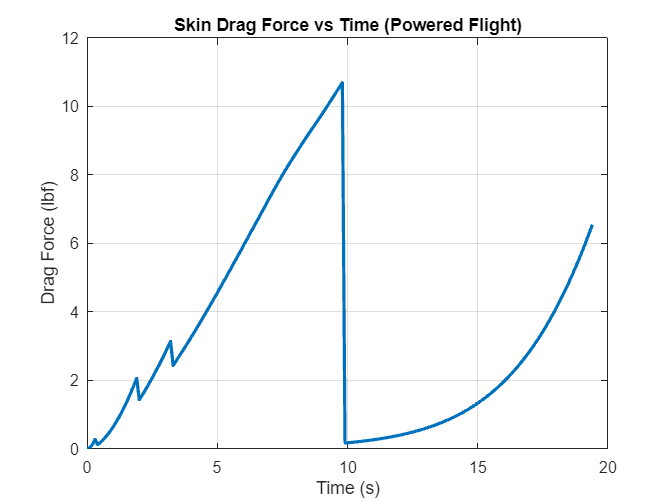

skindragvstime = PrettyPlot(T_Powered, skindrag * 0.224809, "Time (s)", "Skin Drag Force (lbf)", "Skin Drag Force vs Time (Powered Flight)");

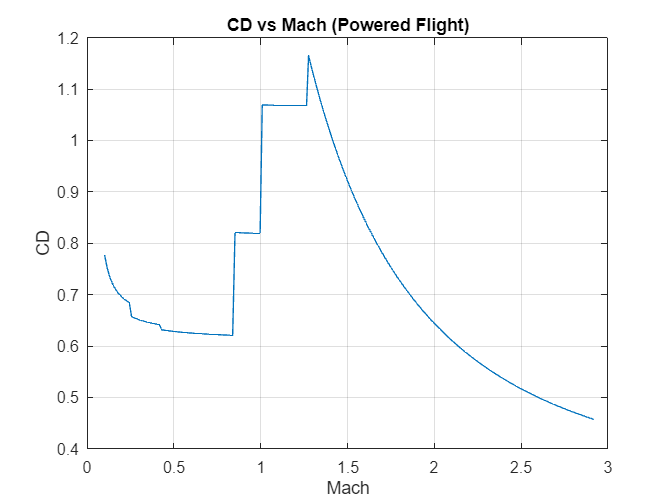

cdvstime = MachPlot(cd, S_Powered, .1);
ylabel("CD")
title("CD vs Mach (Powered Flight)")
grid on

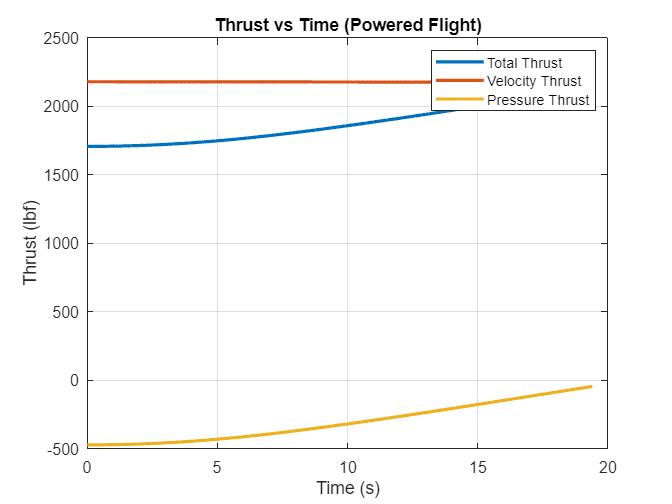

thrustvstime = PrettyPlot(T_Powered, [totalthrust; massthrust; pressurethrust] * 0.224809, "Time (s)", "Thrust (lbf)", "Thrust vs Time (Powered Flight)");
legend(thrustvstime, "Total Thrust", "Velocity Thrust", "Pressure Thrust")

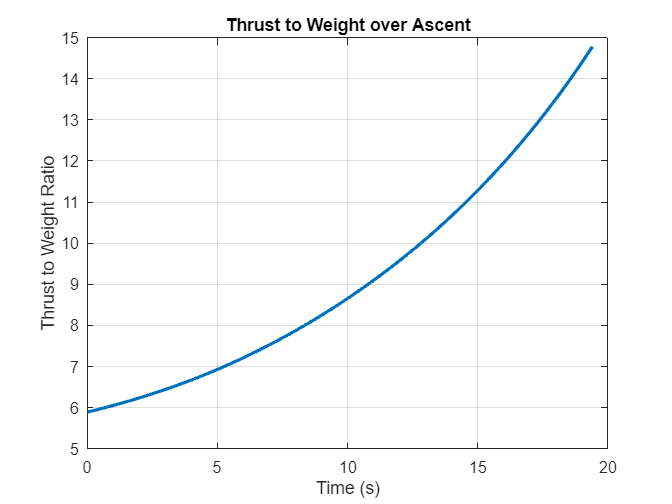

ttwvstime = PrettyPlot(T_Powered, ttw, "Time (s)", "Thrust to Weight Ratio", "Thrust to Weight over Ascent");

sprintf("Max drag force: %d N, mach at point: %.3d, altitude at point: %d m", maxqstuff)

ans = "Max drag force: 3.350324e+03 N, mach at point: 1.275e+00, altitude at point: 2.159372e+03 m"

function plotPhase(T, S)
    Ssize = size(S);
    svarcount = Ssize(2);

    figure

    svars = ["Altitude (m)", "Velocity (m/s)", "Mass (kg)"];
    for i=1:svarcount
        subplot(1,svarcount,i)
        plot(T,S(:,i))
        title(svars(i)+" vs Time (s)")
        xlabel("Time (s)")
        ylabel(svars(i))
    end

end

function [C_D, F_D, skindrag, maxes] = dragAnalysis(T, S, refA, Deneb)
    C_D = [];
    F_D = [];
    skindrag = [];
    maxes = [0, 0, 0];
    for i=S'
        h = i(1);
        v = i(2);
        [~, a, P, rho] = atmosisa(h, "extended","on", "action","None");
        [Fd, skin, pressure, extra] = TotalDrag(h, v, Deneb);
        F_D(end+1) = Fd;
        skindrag(end+1) = skin;
        C_D(end+1) = 2*Fd/refA/rho/(i(2)^2);
        if Fd > maxes(1)
            maxes(1) = Fd;
            maxes(2) = v / a;
            maxes(3) = h;
        end
    end
end

function [thrust, mass, pressure] = thrustAnalysis(T, S, Deneb)
    thrust = [];
    mass = [];
    pressure = [];
    for i=1:length(T)
        h = S(i,1);
        v = S(i,2);
        t = T(i);
        [~, a, P, rho] = atmosisa(h, "extended","on", "action","None");
        [Ft, ~, velt, pt] = Engine(t, P, Deneb);
        thrust(end+1) = Ft;
        mass(end+1) = velt;
        pressure(end+1) = pt;
    end
end

function fig = MachPlot(plotAgainst, S, startAt)
    mach = calcMach(S);
    plotAgainst = plotAgainst(mach>startAt);
    mach = mach(mach>startAt);

    fig = figure;
    plot(mach, plotAgainst)
    xlabel("Mach")
end

function mach = calcMach(S)
    mach = [];
    for i=S'
        [T_, a, P, rho] = atmosisa(i(1), "extended","on", "action","None");
        mach(end+1) = i(2)/a;
    end
end

function Fd=Drag(Cd, refA, rho, v)
    Fd = .5 * Cd * refA * rho * v^2;
end

function pp = PrettyPlot(x, y, xlbl, ylbl, tit)
    pp = plot(x, y, "LineWidth", 2);
    xlabel(xlbl)
    ylabel(ylbl)
    title(tit)
    grid on
end